**2.3 Linear Spatial Filtering**

In linear spatial filtering, typically an input image f(x,y) is convolved with a small spatial filter h(x,y) to create an output image g(x,y),


$$g\left(x,y\right)=\sum_{s=-a}^a \sum_{t=-b}^b f\left(x-s,y-t\right)h\left(s,t\right)=f\left(x,y\right)\otimes h\left(x,y\right)$$


The function h(x,y) can be considered to be the impulse response of the filter system. Another common name for h(x,y) is the point-spread function (PSF).

a. Generate the following filters:


$$h\left(x,y\right)=\frac{1}{2\pi \sigma^2 }e^{-\frac{x^2 +y^2 }{2\sigma^2 }}$$


(i) Y and X-dimensions are 5 and σ = 1.0

(ii) Y and X-dimensions are 5 and σ = 2.0

Normalize the filters such that the sum of all elements equals to 1.0. View the filters as 3D graphs by using the mesh function. These filters are Gaussian averaging filters.

% code for checking against lecture slides:
% hTemp = generatePSFFilter(3, 3, 1.0)
% mesh(hTemp);

h1 = generatePSFFilter(5, 5, 1.0) % (i)

h1 =     0.0030    0.0133    0.0219    0.0133    0.0030
    0.0133    0.0596    0.0983    0.0596    0.0133
    0.0219    0.0983    0.1621    0.0983    0.0219
    0.0133    0.0596    0.0983    0.0596    0.0133
    0.0030    0.0133    0.0219    0.0133    0.0030


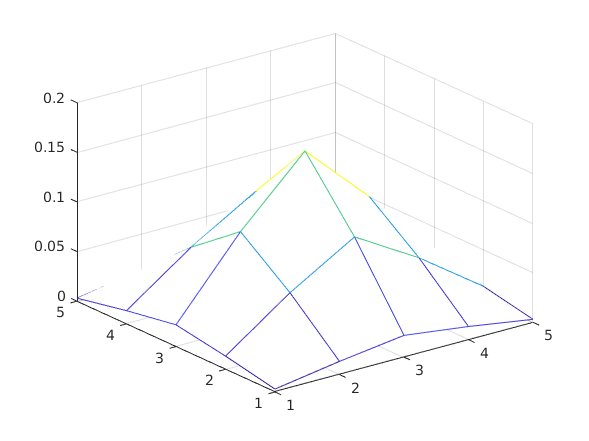

mesh(h1);


h2 = generatePSFFilter(5, 5, 2.0) % (ii)

h2 =     0.0232    0.0338    0.0383    0.0338    0.0232
    0.0338    0.0492    0.0558    0.0492    0.0338
    0.0383    0.0558    0.0632    0.0558    0.0383
    0.0338    0.0492    0.0558    0.0492    0.0338
    0.0232    0.0338    0.0383    0.0338    0.0232


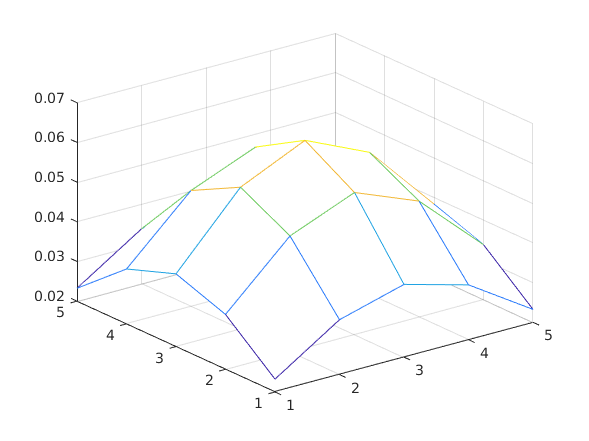

mesh(h2);

b. Download the image ‘ntu-gn.jpg’ from edveNTUre and view it. Notice that this image has additive Gaussian noise.

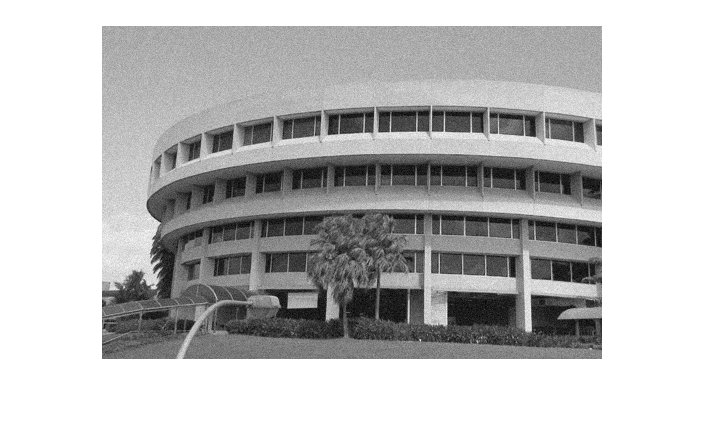

libraryGaussianNoiseImage = imread('images/ntu-gn.jpg');
imshow(libraryGaussianNoiseImage);

c. Filter the image using the linear filters that you have created above using the **conv2** function, and display the resultant images. How effective are the filters in removing noise? What are the trade-offs between using either of the two filters, or not filtering the image at all?

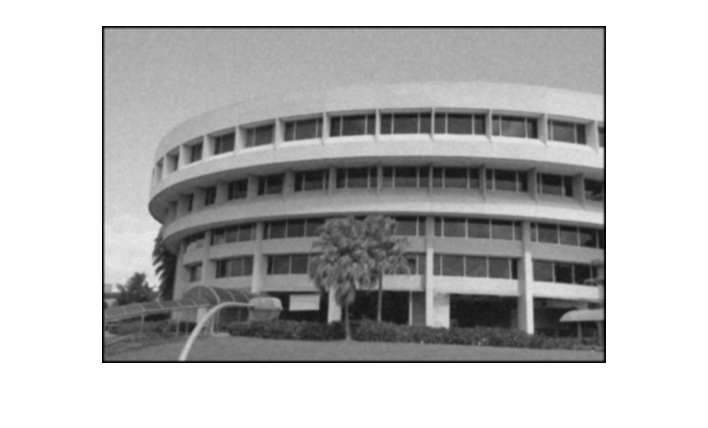

fixedGaussian1 = conv2(libraryGaussianNoiseImage, h1);
imshow(uint8(fixedGaussian1));

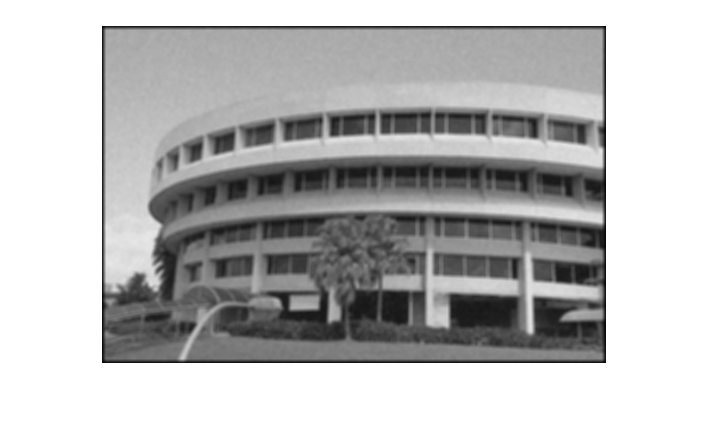


fixedGaussian2 = conv2(libraryGaussianNoiseImage, h2);
imshow(uint8(fixedGaussian2));

how effective filters are in removing noise: noise is gone but images look more blur

trade-offs: not filtering is clearest; higher $\sigma$ makes image more blur

d. Download the image ‘ntu-sp.jpg’ from edveNTUre and view it. Notice that this image has

additive speckle noise.

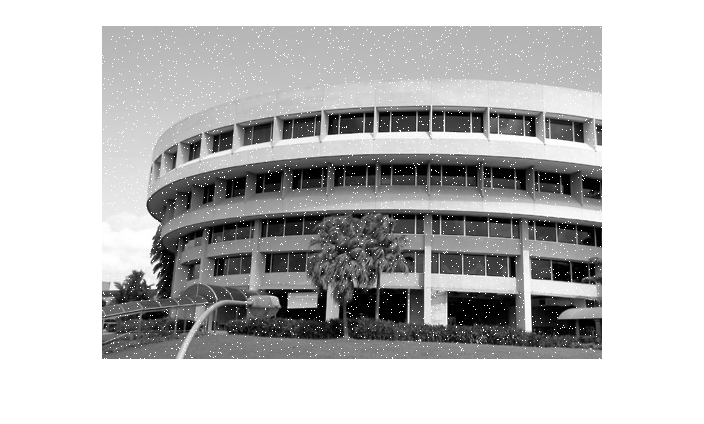

librarySpeckleNoiseImage = imread('images/ntu-sp.jpg');
imshow(librarySpeckleNoiseImage);

e. Repeat step (c) above. Are the filters better at handling Gaussian noise or speckle noise?

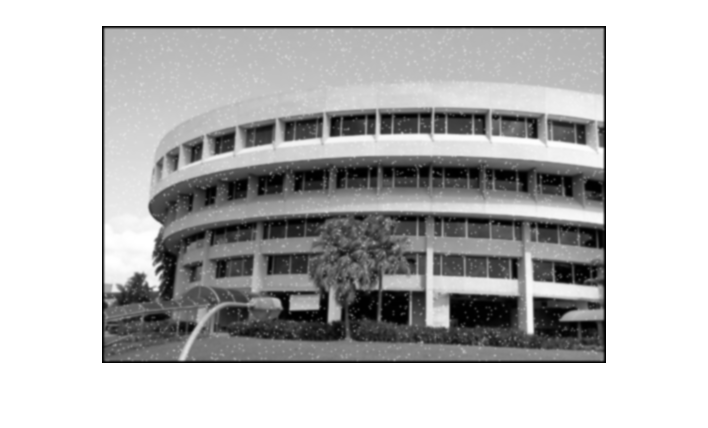

fixedSpeckle1 = conv2(librarySpeckleNoiseImage, h1);
imshow(uint8(fixedSpeckle1));

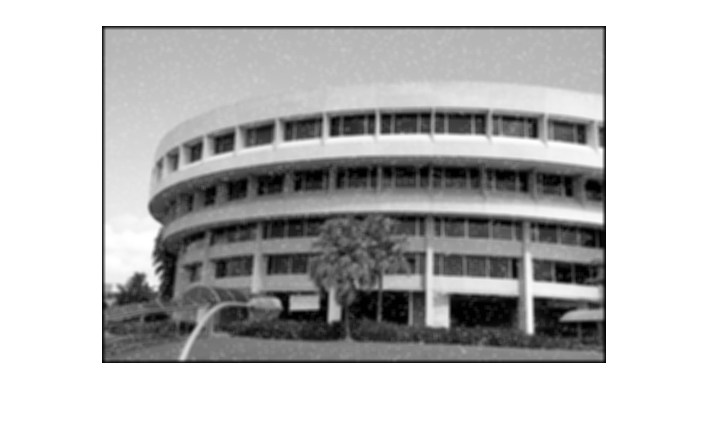


fixedSpeckle2 = conv2(librarySpeckleNoiseImage, h2);
imshow(uint8(fixedSpeckle2));

filters better at handling Gaussian noise or speckle noise: Gaussian - speckle noise can still be seen